# Similarity Transform

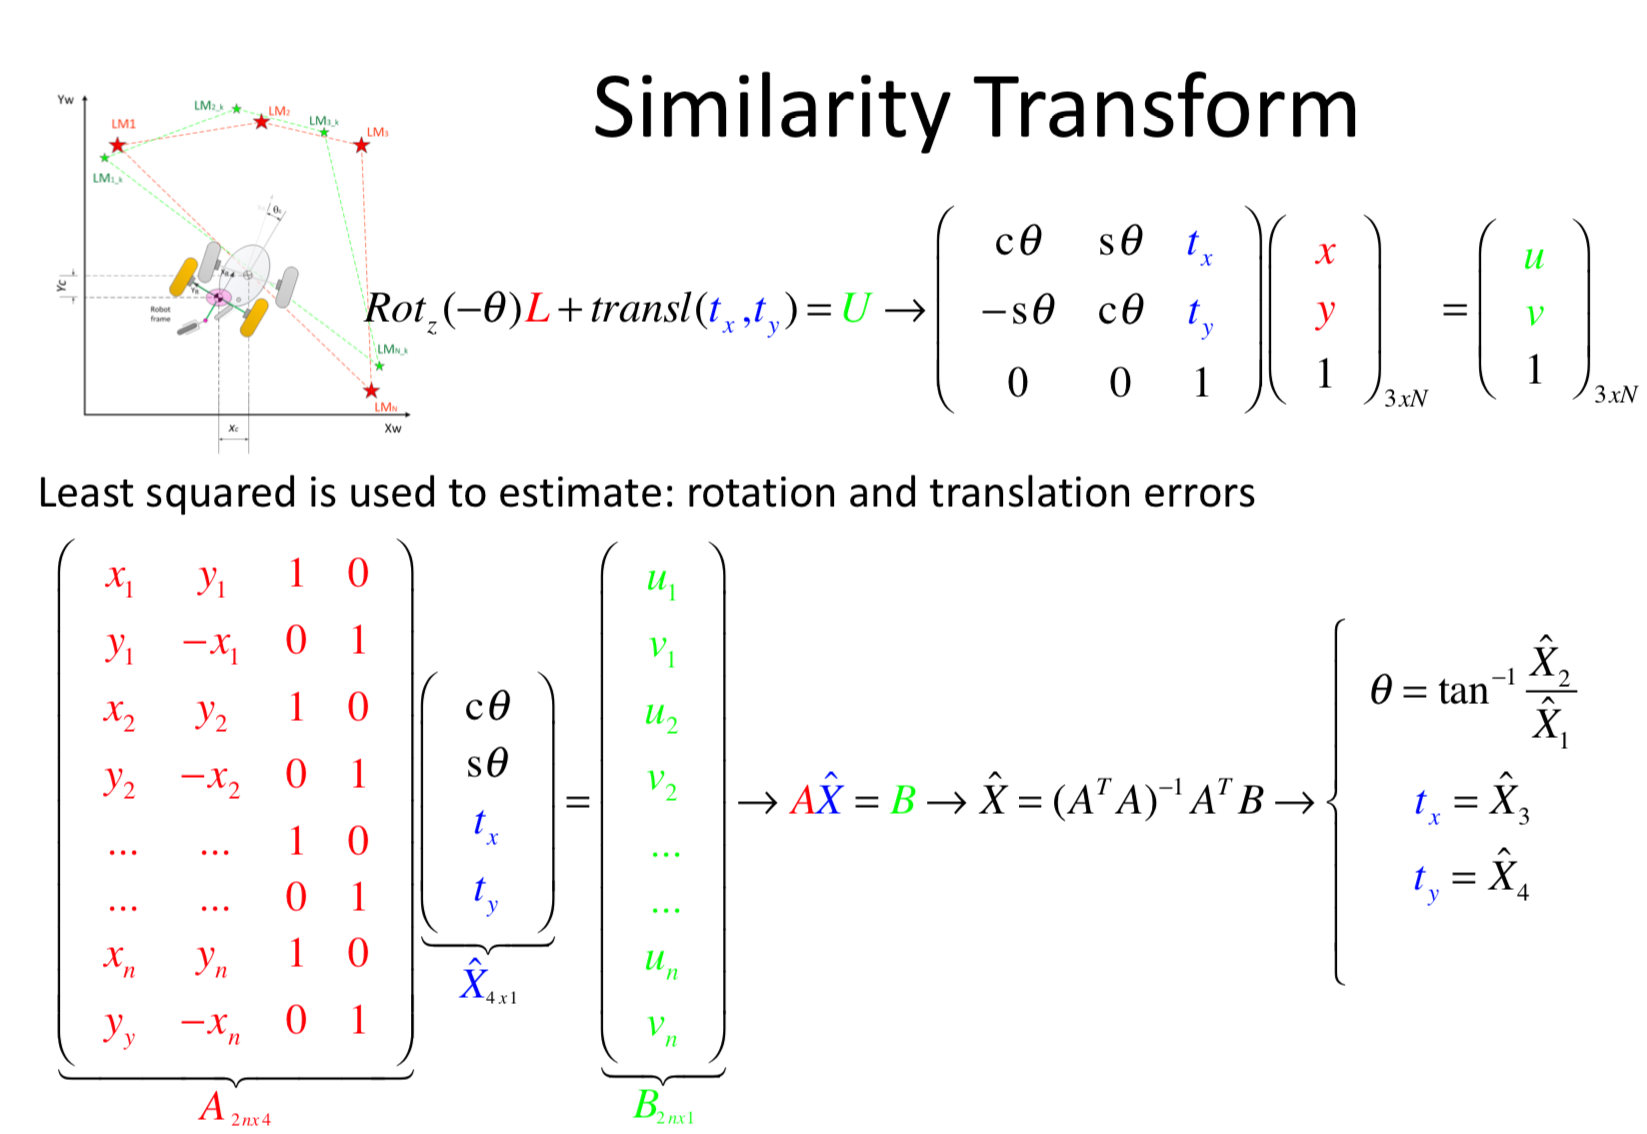

## Land Mark

They are known

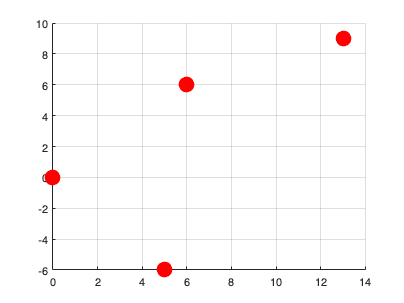

LandMark = [  13,9; 6,6; 0,0;  5, -6]';
figure
axis ([-2 2 -8 10])
scatter(LandMark(1,:),LandMark(2,:),200, 'r','filled');
grid on
hold on

## Simulating innovation

Using Postmultiplication: Translate and rotate the Land Marks

alpha = pi/16 % Rotate pi/16 rad --> 22.5 degrees

alpha = 0.1963

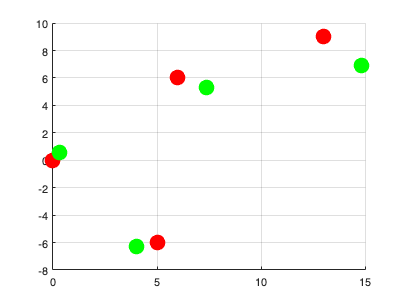

tx = 0.3; % Translate 
ty = 0.6;
RotzTxy = [cos(alpha), sin(alpha), tx;...
          -sin(alpha), cos(alpha), ty;...
           0,           0,          1];
Innovation = RotzTxy*[LandMark;ones(1,4)];
hold on;
scatter(Innovation(1,:), Innovation(2,:),200, 'g','filled');

## Building the Matrices

A = [];
for i=1:size(LandMark, 2)
    A = [A;[LandMark(1,i),LandMark(2,i),1,0]];
    A = [A;[LandMark(2,i),-LandMark(1,i),0,1]]
end

A =     13     9     1     0
     9   -13     0     1


A =     13     9     1     0
     9   -13     0     1
     6     6     1     0
     6    -6     0     1


A =     13     9     1     0
     9   -13     0     1
     6     6     1     0
     6    -6     0     1
     0     0     1     0
     0     0     0     1


A =     13     9     1     0
     9   -13     0     1
     6     6     1     0
     6    -6     0     1
     0     0     1     0
     0     0     0     1
     5    -6     1     0
    -6    -5     0     1


B = [];%Build Matrix B
for i=1:size(Innovation, 2)
    B = [B; Innovation(1,i); Innovation(2,i)]
end

B =    14.8060
    6.8909


B =    14.8060
    6.8909
    7.3553
    5.3142


B =    14.8060
    6.8909
    7.3553
    5.3142
    0.3000
    0.6000


B =    14.8060
    6.8909
    7.3553
    5.3142
    0.3000
    0.6000
    4.0334
   -6.2602


## Finding the error in pose

X = inv((A'*A))*A'*B;
tx_ST = X(3)

tx_ST = 0.3000

ty_ST = X(4)

ty_ST = 0.6000

alpha_ST = atan2(X(2),X(1))

alpha_ST = 0.1963

## Comparing 

tx

tx = 0.3000

ty

ty = 0.6000

alpha

alpha = 0.1963

## Using Laser data

### Land Mark

They are known

LandMark = [  13,9; 6,6; 0,0; 5,-6]';
figure
axis ([-2 14 -8 10])
scatter(LandMark(1,:),LandMark(2,:),200, 'r','filled');
grid on

### Robot Pose with uncertanty

Robot_pose_u=transl(2,-4,0)*trotz(pi/4)
xyz_u=transl(Robot_pose_u)
RPY_u=tr2rpy(Robot_pose_u)

## Robot shape

Robot.V= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

Robot = struct with fields:
    V: [3×4 double]
    F: [1 2 3]


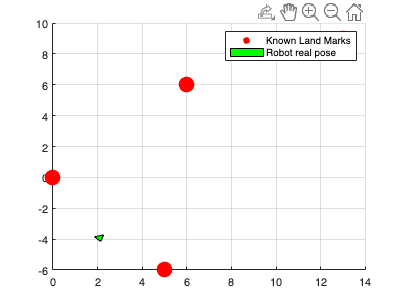

Robot.F = [1,2,3];
hr=[];
hold on

Robot_tr=Robot_pose_u*Robot.V';% moving the robot 
hr=patch(Robot_tr(1,:), Robot_tr(2,:),'g'); 
legend('Known Land Marks','Robot real pose')

### Laser measuring Land Marks

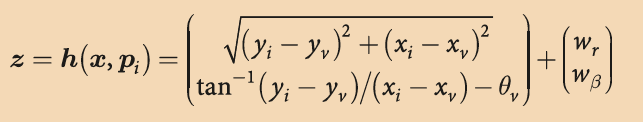

z_laser=@(lm_xy,xy_r, th_r)...
    [sqrt((lm_xy(1)-xy_r(1))^2 +(lm_xy(2)-xy_r(2))^2) atan2((lm_xy(2)-xy_r(2)),(lm_xy(1)-xy_r(1)))-th_r]

z_laser = function_handle with value:
    @(lm_xy,xy_r,th_r)[sqrt((lm_xy(1)-xy_r(1))^2+(lm_xy(2)-xy_r(2))^2),atan2((lm_xy(2)-xy_r(2)),(lm_xy(1)-xy_r(1)))-th_r]


z_lm_139=z_laser([13 9],xyz_u,RPY_u(3))

z_lm_139 =    17.0294    0.0831


### Laser data in Robot Frame


for i = 1:4
z_lm(i,:)=z_laser(LandMark(:,i),xyz_u,RPY_u(3));
lxy_rf_u(:,i)=[z_lm(i,1)*cos(z_lm(i,2)) z_lm(i,1)*sin(z_lm(i,2))];
end


### Estimated Robot Pose (no noise)

Remember laser pose with noise [2 -4 pi/4]

Robot_pose=transl(4,-2,0)*trotz(pi/4)

Robot_pose =     0.7071   -0.7071         0    4.0000
    0.7071    0.7071         0   -2.0000
         0         0    1.0000         0
         0         0         0    1.0000


xyz=transl(Robot_pose)

xyz =      4
    -2
     0


RPY=tr2rpy(Robot_pose)

RPY =          0         0    0.7854


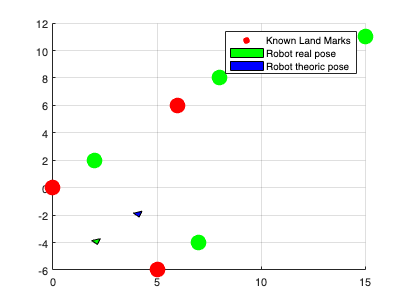

Robot_tr=Robot_pose*Robot.V';% moving the robot 
hr=patch(Robot_tr(1,:), Robot_tr(2,:),'b'); 
legend('Known Land Marks','Robot real pose','Robot theoric pose')

### Mapped Land Mark

hold on
LandMark_u=Robot_pose*[lxy_rf_u; 0 0 0 0; 1 1 1 1]

LandMark_u =    15.0000    8.0000    2.0000    7.0000
   11.0000    8.0000    2.0000   -4.0000
         0         0         0         0
    1.0000    1.0000    1.0000    1.0000


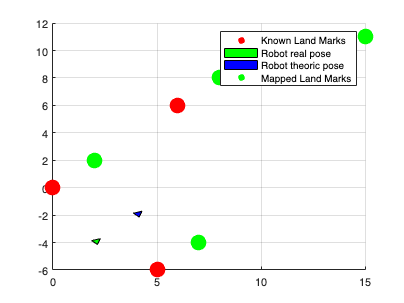

scatter(LandMark_u(1,:),LandMark_u(2,:),200, 'g','filled');
legend('Known Land Marks','Robot real pose','Robot theoric pose', 'Mapped Land Marks')

## Repeating the example

B = [];%Build Matrix B
for i=1:size(LandMark_u, 2)
    B = [B; LandMark_u(1,i); LandMark_u(2,i)]
end

B =    15.0000
   11.0000


B =    15.0000
   11.0000
    8.0000
    8.0000


B =    15.0000
   11.0000
    8.0000
    8.0000
    2.0000
    2.0000


B =    15.0000
   11.0000
    8.0000
    8.0000
    2.0000
    2.0000
    7.0000
   -4.0000


## Finding the error in pose

X = inv((A'*A))*A'*B;
tx_ST = X(3)

tx_ST = 2.0000

ty_ST = X(4)

ty_ST = 2.0000

alpha_ST = atan2(X(2),X(1))

alpha_ST = 2.1511e-16